# Filament Analysis: Width and Length

        Last modified by Cristel Chandre (December 7, 2021)

        Comments? [cristel.chandre@cnrs.fr](mailto:cristel.chandre@cnrs.fr) 

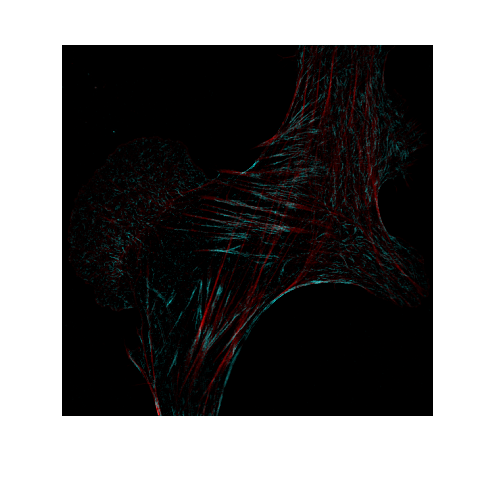

pixel_size = 20.3127;
save_fig =  true;
save_data = true;
save_profile = true;
option_menu = 1;

close all
[file, path] = uigetfile('*.tif','*.tiff');
[~, name, ~] = fileparts([path file]);
tiff_info = imfinfo([path file]);
n_channels = size(tiff_info,1);
selected_channel = 1;
annex_channel = 2;
analyze_annex = true;
if selected_channel<=n_channels
    I = imread([path file],selected_channel);
else
    I = imread([path file],1);
end
if annex_channel<=n_channels
    I_a = imread([path file],annex_channel);
    I_composite = imfuse(I,I_a,'falsecolor','Scaling','joint','ColorChannels',[2 1 1]);
else
    I_composite = I;
end
if analyze_annex==true
    na = 2;
else
    na = 1;
end
data = [];
itdata = 1;
fig_I = figure('Units','centimeters','Position',[30 20 30 30]);
imshow(I_composite,'InitialMagnification','fit')

## FWHM

if option_menu==1
    option_label = 'Width';
    while true 
        roi = drawline('Color','cyan','LineWidth',2,'MarkerSize',1,'Label',num2str(itdata),'LabelAlpha',0.5);
        xv = roi.Position(:,1);
        yv = roi.Position(:,2);
        pixvals = improfile(I,xv,yv);
        [pks,locs,w,p] = findpeaks(pixvals,'SortStr','descend');
        if  analyze_annex==true
            pixvals_a = improfile(I_a,xv,yv);
            [pks_a,locs_a,w_a,p_a] = findpeaks(pixvals_a,'SortStr','descend');
        end
        fig_peaks = figure('Visible','on','Units','centimeters','Position',[10 10 20 20]);
        subplot(na,1,1)
        findpeaks(pixvals,'Annotate','extents','WidthReference','halfheight')
        set(gca,'box','on','FontSize',20,'LineWidth',2)
        title('Profile (main)')
        if na==2
            subplot(na,1,2)
            findpeaks(pixvals_a,'Annotate','extents','WidthReference','halfheight')
            set(gca,'box','on','FontSize',20,'LineWidth',2)
            title('Profile (annex)')
        end
        xlabel('Pixels','FontSize',26)
        answer = questdlg('Do you want to save this ROI?','Options','Save','Skip','Quit','Skip');
        switch answer
            case 'Save'
                if na==1
                    if isempty(w)==true
                        w1val = NaN;
                    else
                        w1val = w(1)*pixel_size;
                    end
                    newdata = [itdata,w1val];
                else
                    if isempty(w)==true
                        w1val = NaN;
                    else
                        w1val = w(1)*pixel_size;
                    end
                    if isempty(w_a)==true
                        w2val = NaN;
                    else
                        w2val = w_a(1)*pixel_size;
                    end
                    newdata = [itdata,w1val,w2val];
                end
                if save_profile==true
                    savefig(fig_peaks,[path name '_' num2str(itdata) '.fig'])
                    if na==1
                        save([path name '_' num2str(itdata) '.mat'],"pixvals")
                    else
                        save([path name '_' num2str(itdata) '.mat'],"pixvals","pixvals_a")
                    end  
                end
                data = [data;newdata];
                itdata = itdata+1;
            case 'Skip'
                delete(roi)
            case 'Quit'
                delete(roi)
                close(fig_peaks)
                break
        end
        close(fig_peaks)
    end
    zoom out
end

Invalid or deleted object.

Error in images.roi.Line/get.Position

## Length

if option_menu==2
    option_label = 'Length';
    while true 
        roi = drawfreehand('Closed',false,'Color','cyan','FaceAlpha',0,'LineWidth',2,'MarkerSize',1,'Label',num2str(itdata),'LabelAlpha',0.5,'Smoothing',2);
        xv = roi.Position(:,1);
        yv = roi.Position(:,2);
        curveLength = sum(vecnorm(diff([xv,yv]),2,2))*pixel_size;
        answer = questdlg('Do you want to save this ROI?','Options','Save','Skip','Quit','Skip');
        switch answer
            case 'Save'
                newdata = [itdata,curveLength];
                data = [data;newdata];
                itdata = itdata+1;
            case 'Skip'
                delete(roi)
            case 'Quit'
                delete(roi)
                break
        end
    end
    zoom out
end

## Save figures and data

filename = [name '_' option_label];
if save_fig==true
    zoom out
    saveas(gcf,[path filename '.tiff'])
    disp(['Save figure as ' filename '.tiff'])
end
if save_data==true
    save([path filename '.txt'],'data','-ascii');
    disp(['Save data as ' filename '.txt'])
end
close all

Copyright (c) 2021 Cristel Chandre.

All rights reserved.

Redistribution and use in source and binary forms are permitted provided that the above copyright notice and this paragraph are duplicated in all such forms and that any documentation, advertising materials, and other materials related to such distribution and use acknowledge that the software was developed by the CNRS. The name of the CNRS may not be used to endorse or promote products derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED "AS IS" AND WITHOUT ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, WITHOUT LIMITATION, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE.